# Customize Table Column Separators

To customize the lines that separate table columns, set the properties of an `mlreportgen.ppt.ColSep` object and add the object to the `Style` property of an `mlreportgen.ppt.Table` object. This example makes the column separators dashed and red, with a line width of three points.

Create a presentation.

import mlreportgen.ppt.*
ppt = Presentation("myColSep.pptx");
open(ppt);

Add a slide to the presentation.

slide = add(ppt,"Title and Table");

Create a table and set custom column separators.

t = Table(magic(3));
t.Style = [t.Style {ColSep("dash","red","3pt")}];

Add a title and the table to the slide.

replace(slide,"Title","Table with custom column separators");
replace(slide,"Table",t);

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the table in the generated presentation:

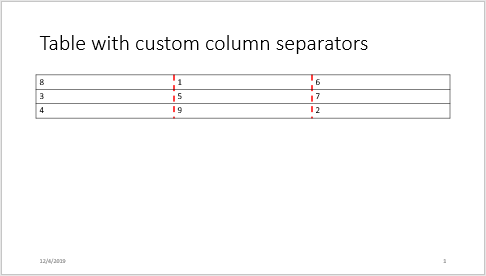

*Copyright 2019 The MathWorks, Inc.*